clear
load data2.mat
n=length(data.CzasLokalnyUTC0000)

n = 516459

T=5; %[s]
fs=1/T; %[Hz]
t_all=T*(0:n-1);

Kompresor1=data.Kompresor1;
Wlot=0.1*data.Wlot;
TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
X=[Kompresor1,Wlot,TemperaturaOtoczenia];
[X,~]  = GetRidOfNans(X);
day=24*60*60*fs

day = 17280

t=T*(1:day);
X=X';
X=X(:,1:day);

x=X(1,:);
y=X(2,:);
Tar=X(3,:);

R=3.5;
C=30;
G=30;


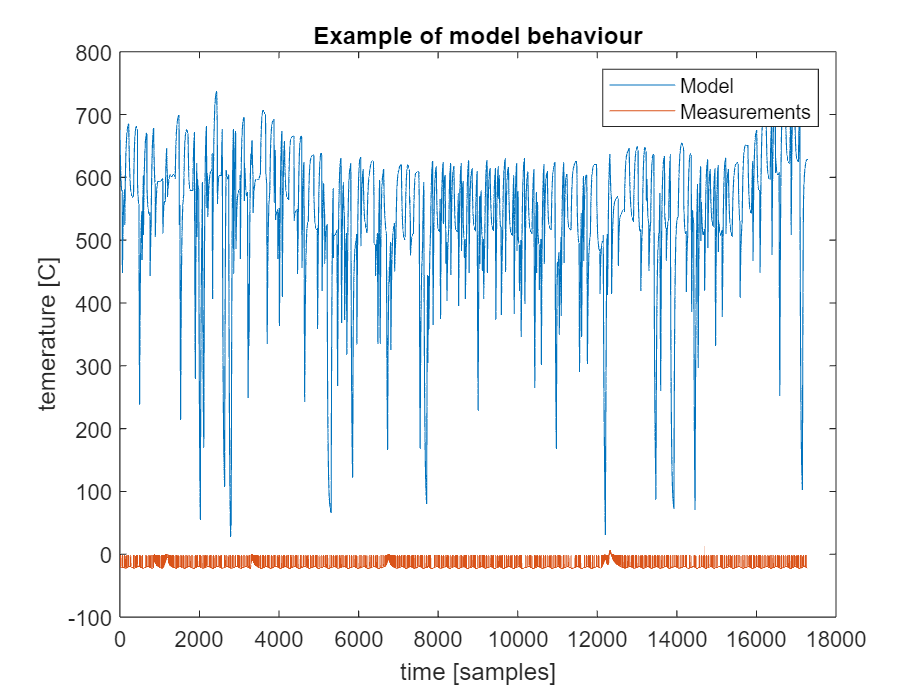

y1=ModelFunction(-x',Tar',G,R,C,t);

plot(y1); hold on
plot(y);hold off
title('Example of model behaviour')
xlabel('time [samples]')
ylabel('temerature [C]')
legend('Model','Measurements')


    % A simple random optimization algorithm. It tries new locations until it
% runs out of time. Delay serves as a way of slowing FunctionPlot.
% It requires a function for optimization (any function from folder
% "FunctionsForOptimization"
 


%% Adjustable parameters:
MaxRangeR = [1 100];  % Range of parameters for optimization
MaxRangeC = [1 100];
MaxRangeTa = [1 100];
 
MaxSteps = 1000;         % How many iterations do we perform?
FunctionPlot = 0;       % change to 0 If you want to get rid of the underlying function plot 
PointPlot = 0;          % Change to 0 if you want to get rid of the visualization
ConvergenceColor = 'r'; % Change color of the convergence curve here
%close all              % Comment this out if you want to have many convergence curves plotted
 
ViewVect = [0,90];             % Initial viewpoint
Delay = 0.001;                 % Inter-loop delay  - to slow down the visualization
FunctionPlotQuality = 0.05;    % Quality of function interpolation. Lower for a quicker run
 
%% Map initialization
InitialRangeR = MaxRangeR;      % This is the range from which we can draw points.
InitialRangeC = MaxRangeC;
InitialRangeTa = MaxRangeTa;
%% Storing of a best solution
    CurrentMin = 50000;
    ResultR = 1;
    ResultC = 1;
    ResultTa = 1;
%% The main optimization loop
    EndingCondition = 0;
    iter = 0;
    tic;
 
    
    InitialStep = 10; % Exploration/exploitation balance parameters:
    P1 = 2;
    P2 = 60;

    % lr_values = expDecay_of_learningRate(300, 1, MaxSteps*2);
% Random selection of a candidate for optimum:
    NewR = InitialRangeR(1) +  rand()*(InitialRangeR(2) - InitialRangeR(1));
    NewC = InitialRangeC(1) +  rand()*(InitialRangeC(2) - InitialRangeC(1));
    NewTa = InitialRangeTa(1) +  rand()*(InitialRangeTa(2) - InitialRangeTa(1));

    for repetition = 1:1
    
        CurrentMin = 50000;
ResultR = 1;
ResultC = 1;
ResultTa = 1;
EndingCondition = 0;
iter = 0;

    while(EndingCondition == 0)
        iter = iter + 1;
        Step(iter) = InitialStep * (1/(1+exp((iter-(MaxSteps/P1))/P2)));
        % Step(iter)=lr_values(iter);
        NewR = ResultR+Step(iter)*randn();
        NewC = ResultC+Step(iter)*randn();
        NewTa = ResultTa+Step(iter)*randn();
        % Check for constraints (they could be different than the range
        % from which we draw our solutions)
        NewR = min(MaxRangeR(2),max(NewR,MaxRangeR(1)));
        NewC = min(MaxRangeC(2),max(NewC,MaxRangeC(1)));
        NewTa = min(MaxRangeC(2),max(NewTa,MaxRangeC(1)));
        if NewR == 0 
            NewR=1;
        end
        if NewC == 0
            NewC=1;
        end
 
% If you'd like to provide function as a 2D image or use here any other objective function, 
% following line needs to be modified. The 0 passed to the function denotes the fact,
% that the function is constant in time.
        
        y1=ModelFunction(x',Tar',NewTa,NewR,NewC,t);
        CurrentValue = rmse(y,y1);
               
        
        if(CurrentValue < CurrentMin)
            CurrentMin = CurrentValue;  % Storing of a historically best result
            ResultR = NewR;
            ResultC = NewC;
            ResultTa = NewTa;
            
        
        
        % % Command-window stuff for monitoring of algorithm's progress:
        % SimTime = toc;
        % clc
        % fprintf('\nCurrent best:  %f',CurrentMin);
        % fprintf('\nCurrent:       %f',CurrentValue);
        % fprintf('\n\n\n');
        % fprintf('\nIteration:     %d',iter);
        % fprintf('\nTime:          %d',SimTime);
        
        BestHistory(iter) = CurrentMin;         % Here we store our historically best result
        CurrentHistory(iter) = CurrentValue;    % Here we store our currently investigated result
        
    if(iter >= MaxSteps)
        EndingCondition = 1;    % To stop the while loop from running
    else 
        
    end
        % If we'd like to slow down the simulation - this line is where it
        % is done:
        pause(Delay);
        Results(repetition) = BestHistory(end);
    end
    end
    end

Unable to perform assignment because the indices on the left side are not compatible with the size of the right side.

    figure(2);
    plot(BestHistory,'Color',ConvergenceColor); hold on      
    plot(CurrentHistory,'Color',ConvergenceColor,'LineStyle',':'); hold on
    xlabel('Iteration number');
    ylabel('Objective function value');
    figure(4);
plot(Step);
xlabel('iteration');
ylabel('step value');
meanjpjvs=mean(Results);
stdjpjvs=std(Results);
disp(meanjpjvs);
disp(stdjpjvs);

Ta=ResultTa;
Ta=Ta*ones(N,1);
y1=ModelFunction(x,Ta,2,ResultR,ResultC,t);
figure
plot(y);hold on
plot(y1);hold off
